# Testing center of mass equation

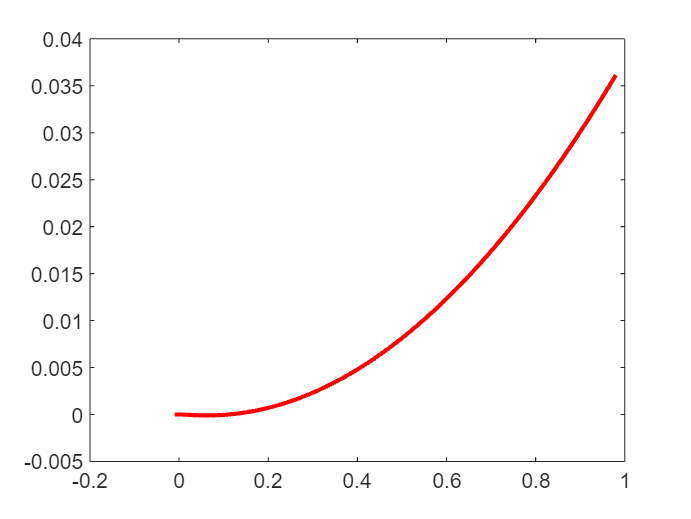

clearvars;
N = 250;
dt = 0.01; froude_nb = 1;
Al = (rand(1, N)-1/2)./linspace(20, 40, N); Al(1) = 0; % Small amplitudes random initial condition
Al_velocities = zeros(1, N);
contact_angle = 3*pi/4;
contact_radius = r_from_spherical(contact_angle, Al);
press = @(ang) 3.8 * (ang > contact_angle); % Initial pressure distribution
Bl = project_amplitudes(press, N, [0, pi], nan, true);
probable_next_conditions = struct("pressure_amplitudes", Bl, ...
    "contact_radius", contact_radius, "nb_harmonics", N, ...
    "deformation_amplitudes", Al, "dt", dt);

current_conditions = struct("deformation_amplitudes", Al, ...
    "pressure_amplitudes", Bl, "nb_harmonics", N, "current_time", 0, ...
    "center_of_mass", 0, "center_of_mass_velocity", 0, "dt", dt);
previous_conditions = {current_conditions current_conditions};

previous_conditions{1}.current_time = ...
    previous_conditions{2}.current_time - dt;
previous_conditions{1}.center_of_mass_velocity = ...
    previous_conditions{2}.center_of_mass_velocity + dt/froude_nb;
previous_conditions{1}.center_of_mass = ...
    previous_conditions{2}.center_of_mass - previous_conditions{2}.center_of_mass_velocity * dt;
    
rk = dt/previous_conditions{end}.dt; n = 2;
ak = (1+2*rk)/(1+rk);
bk = -(1+rk);
ck = rk^2/(1+rk);
coefs = [ck, bk, ak]; 

PROBLEM_CONSTANTS = struct("froude_nb", froude_nb, "CM", 9, "nb_harmonics", N);

g = zeta_generator(Al);
y = @(ang) cos(ang) .* (1 + g(ang));
x = @(ang) sin(ang) .* (1 + g(ang));
dang = 1e-8;
der = @(f, ang) (f(ang-dang) - f(ang))/dang;
norm = @(ang) sqrt(der(x, ang).^2 + der(y, ang).^2);

% z-coordinate of the normal
inner_product = @(ang) (x(ang) - x(ang-dang))./(norm(ang) *dang);
dA = @(ang) (1 + g(ang)).^2 .* sin(ang) * 2 * pi;

M = 100;
CM_manual = zeros(1, M); CM_manual(1) = previous_conditions{1}.center_of_mass; 
CM_manual(2) = previous_conditions{2}.center_of_mass;
CM = zeros(1, M); CM(1:2) = CM_manual(1:2);
t = zeros(1, M); t(1) = previous_conditions{1}.current_time;
t(2) = previous_conditions{2}.current_time;

extract_symbol = @(field, ss) arrayfun(@(jj) ss{jj}.(field), 1:n);

% Advancing time steps
for ii = 3:M
    % Manual force
    F_manual = @(ang) press(ang) .* inner_product(ang) .* dA(ang);
    
    d2zd2t = integral(F_manual, 0, pi, 'RelTol',1e-4)/ (4*pi/3);
    d2zd2t = -1/PROBLEM_CONSTANTS.froude_nb - d2zd2t;
    CM_velocity  = (dt * d2zd2t - sum(coefs(1:n) .* extract_symbol('center_of_mass_velocity', previous_conditions)))/coefs(end);
    CM_manual(ii) = (dt * CM_velocity -  sum(coefs(1:n) .* extract_symbol('center_of_mass', previous_conditions)))/coefs(end);
    CM(ii) = get_center_of_mass(Al, Al_velocities, probable_next_conditions, ...
        previous_conditions, PROBLEM_CONSTANTS);
    % Copying last tie format
    new_conditions = previous_conditions{end};
    new_conditions.center_of_mass = CM_manual(ii);
    new_conditions.center_of_mass_velocity = CM_velocity;
    new_conditions.current_time = previous_conditions{end}.current_time + dt;
    new_conditions.dt = dt; t(ii) = new_conditions.current_time;
    previous_conditions = {previous_conditions{end} new_conditions};
end

plot(t, CM_manual);
hold on;
plot(t, CM, '-r','LineWidth',2 );


hold off;